# **[Self] MiniQuiz Lec14 [ALL CORRECT]**

## Q1 [CORRECT]

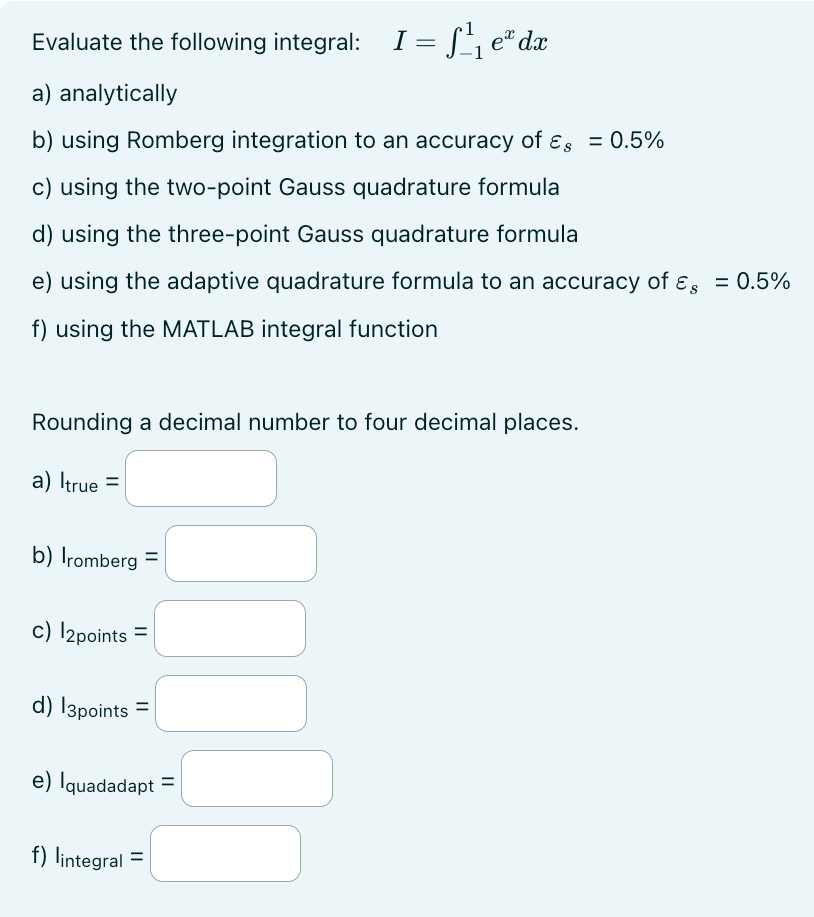

### a

f = @(x) exp(x);
a = -1;
b = 1;
Itrue = integral(f, a, b)

Itrue = 2.3504

### b

Irb = romberg(f, a, b, 0.5)

Irb = 2.3505

% [Irb, ea, iter] = romberg(f, a, b, 0.5)

### c

a1 = (b+a)/2;
a2 = (b-a)/2;
f2 = @(xd) exp(a1 + a2*xd) * a2;

c0 = 1; c1 = 1;
x0 = -1/sqrt(3); x1 = 1/sqrt(3);
Ig2p = c0*f2(x0) + c1*f2(x1)

Ig2p = 2.3427

### d

c0 = 5/9;
c1 = 8/9;
c2 = 5/9;
x0 = -sqrt(3/5);
x1 = 0;
x2 = sqrt(3/5);
Ig3p = c0*f2(x0) + c1*f2(x1) + c2*f2(x2)

Ig3p = 2.3503

### e

Iqa = quadadapt(f, a, b, 0.5)

Iqa = 2.3505

### f

Iint = integral(f, a, b) % basically the same as Itrue

Iint = 2.3504

## Q2 [CORRECT]

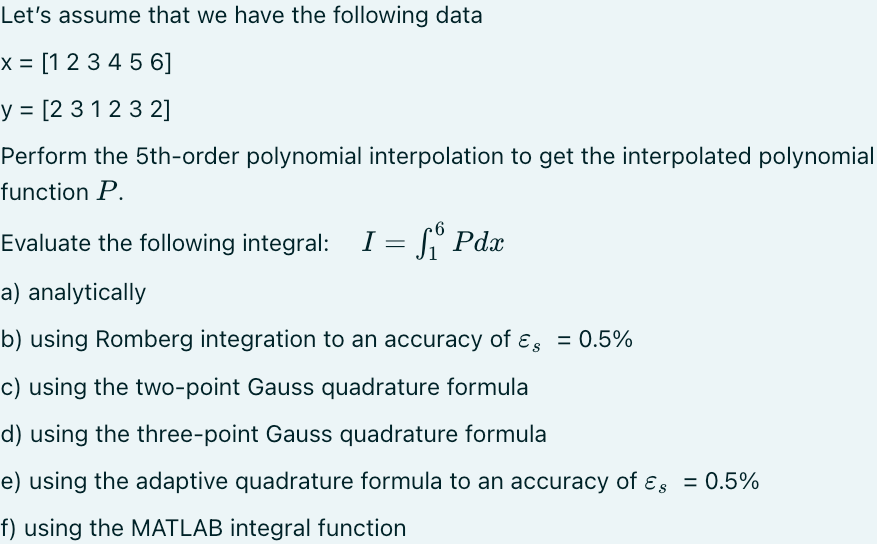    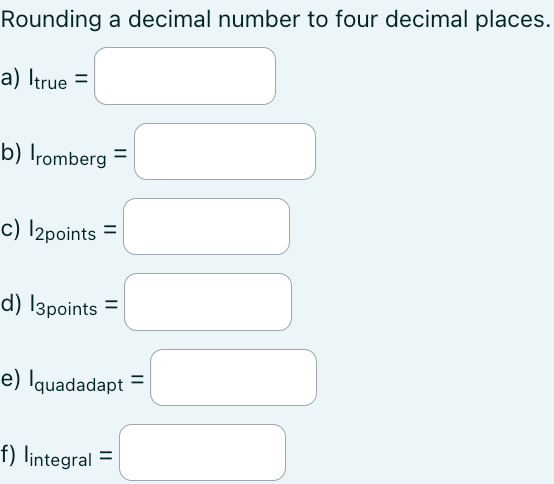

x  = [1 2 3 4 5 6];
y  = [2 3 1 2 3 2];
p5 = polyfit(x, y, 5)

p5 =     0.0833   -1.6250   11.8333  -39.3750   58.0833  -27.0000


f  = @(x) p5(1).*x.^5 + p5(2).*x.^4 + p5(3).*x.^3 + p5(4).*x.^2 + p5(5).*x + p5(6);

### a

a = 1;
b = 6;
Itrue = integral(f, a, b)

Itrue = 11.7361

### b

Irb = romberg(f, a, b, 0.5)

Irb = 11.7361

% [Irb, ea, iter] = romberg(f, a, b, 0.5)

### c

a1 = (b+a)/2;
a2 = (b-a)/2;
f2 = @(xd) ( p5(1).*(a1 + a2*xd).^5 + ...
            p5(2).*(a1 + a2*xd).^4 + ...
            p5(3).*(a1 + a2*xd).^3 + ...
            p5(4).*(a1 + a2*xd).^2 + ...
            p5(5).*(a1 + a2*xd) + ...
            p5(6) ) * a2;

c0 = 1; c1 = 1;
x0 = -1/sqrt(3); x1 = 1/sqrt(3);
Ig2p = c0*f2(x0) + c1*f2(x1)

Ig2p = 14.6296

### d

c0 = 5/9;
c1 = 8/9;
c2 = 5/9;
x0 = -sqrt(3/5);
x1 = 0;
x2 = sqrt(3/5);
Ig3p = c0*f2(x0) + c1*f2(x1) + c2*f2(x2)

Ig3p = 11.7361

### e

Iqa = quadadapt(f, a, b, 0.5)

Iqa = 11.7361

### f

Iint = integral(f, a, b) % basically the same as Itrue

Iint = 11.7361